# Manuscript plots

Set-up

clearvars
close all
desktop = 0;
laptop=1;
if desktop
    addpath(genpath('C:\Users\Clara Douglas\OneDrive - University of Southampton\PhD\Projects\carbonuptakeinwg'))
    cd 'C:\Users\Clara Douglas\OneDrive - University of Southampton\PhD\Projects\carbonuptakeinwg\data\processed' % desktop
    addpath(genpath('C:\Users\Clara Douglas\OneDrive - University of Southampton\PhD\Matlab Add-ins'));
elseif laptop
    addpath(genpath('C:\Users\ccd1n18\Documents\Projects\CarbonUptakeInWG'))
    cd 'C:\Users\ccd1n18\Documents\Projects\CarbonUptakeInWG\data\processed' % laptop
    addpath(genpath('C:\Users\ccd1n18\Documents\Projects\m_map'));
    addpath(genpath('C:\Users\ccd1n18\Documents\Projects\SetCMap'));
end

## Figure 1: (a) Map of timeseries average NPP (g C m^-2 a^-1). (B) Barplot of total NPP per year for each subregion (left x-axis) and minimum sea ice area // sea ice difference for the entire Weddelll Gyre on the right y-axis).

[Compile as single figure in Affinity to then be saved as PDF]

part A

% Load data
load('ProcessedCAFEArrays_May22.mat')
load('WAPSHelfOpenJan22.mat')
load('box_lat_lons.mat', 'andrex_box')
load('SouthernBoundary_Orsi1995.mat')
ShelfBox=ShelfMinusWAPJan22;%shelf_region_ANDbox
OOBox=OpenOceanMinusWAPJan22;%open_ocean_ANDbox
WAPBox=WAPJan22;
colors=[[0.27,0.8,0.01];[0.8 0.4 0];[0.44 0.78 0.91]]; % .15 .3 .2 dark green
c=[colors(2,:);[1 1 0];colors(1,:)];

% calculate mean NPP
NPPAnRate_mean=mean(AnnualNPPRate_gperyear(:,:,1:18),3,'omitnan');
[NPPAnRate_max,I]=max(AnnualNPPRate_gperyear(:,:,1:18),[],3,'omitnan');
% to get the average for pixels across the whole time, including when they
% were ice covered
NPPrtemp=AnnualNPPRate_gperyear(:,:,1:18);
NPPrtemp(isnan(NPPrtemp))=0;
NPPAnRate_mean2=mean(NPPrtemp(:,:,:),3);
NPPAnRate_mean2(NPPAnRate_mean2==0)=NaN;

% make the map
LAT_MIN = -80; LAT_MAX = -50; LONG_MIN = -75; LONG_MAX = 35;
xin=lon_wg; yin=lat_wg; zin=NPPAnRate_mean2; zin2=NPPAnRate_mean;
Proj_List = {'Stereographic';'Orthographic';'Azimuthal Equal-area';...
    'Azimuthal Equidistant';'Gnomonic';'Satellite';...
    'Albers Equal-Area Conic';'Lambert Conformal Conic';'Mercator';...
    'Miller Cylindrical';'Equidistant Cylindrical';'Oblique Mercator';...
    'Transverse Mercator';'Sinusoidal';'Gall-Peters';'Hammer-Aitoff';...
    'Mollweide';'Robinson';'UTM';};
proj=8;
Projection = Proj_List{proj};
% Projection inputs
if proj < 7
    %     m_proj(Projection, 'lon',(LONG_MIN+LONG_MAX)./2,'lat',(LAT_MIN+LAT_MAX)./2,'rad',90 | -30 -50, 'alt',1); %For projs 1-6\
    m_proj(Projection, 'lon',0,'lat',-90,'rad',-70, 'alt',45); %For projs 1-6\
elseif proj == 7 || proj == 8
    m_proj(Projection,'lon',[LONG_MIN LONG_MAX],'lat',[LAT_MIN LAT_MAX],'clo',-15,'par',[-80 -45],'ell','normal'); %For projs 7-8
elseif proj == 9 || proj == 10 || proj == 11
    m_proj(Projection,'lon',[LONG_MIN LONG_MAX],'lat',[LAT_MIN LAT_MAX]); %For projs 9-11
elseif proj == 12
    m_proj(Projection,'lon',[-200 LONG_MAX],'lat',[LAT_MIN LAT_MAX],'asp',100,'dir','horizontal') % For projs 12
elseif proj == 19
    m_proj(Projection,'lon',[LONG_MIN LONG_MAX],'lat',[LAT_MIN LAT_MAX],'hem',0,'ell','grs80'); %For proj 19
else
    m_proj(Projection,'lon',[LONG_MIN LONG_MAX],'lat',[LAT_MIN LAT_MAX],'clo',-30); %For projs 13-18 -30
end

figure;
set(gcf, 'Units', 'centimeters', 'Position', [0 0 50 60],...
    'PaperUnits', 'centimeters', 'PaperSize', [60 80]);
m_pcolor(xin,yin,zin)
shading interp
set(0,'DefaultAxesColor','none')
caxis([0 100]);
cmap=cmocean('delta');%,250,'pivot',120);
% cmap(1,:)=1;
colormap(cmap)
hold on
% [C,h]=m_contour(xin,yin,zin,[50:50:100],'w');
% [C2,h2]=m_contour(xin,yin,zin,[200:100:400],'w');
% clabel(C,h,'Color','w','FontSize',12)
% clabel(C2,h2,'Color','w','FontSize',12)
hh=colorbar;
ylabel(hh,'g C m^-^2 a^-^1','FontSize',12);
hh.Location='southoutside'; % want to make it a bit shorter still
hh.Position = [0.28 0.09 0.5 0.05];

m_plot(sbdy(:,1),sbdy(:,2),'color',[.8 .8 .8],'linewi',1.25,'LineStyle','-')
SR_line=m_plot(ShelfBox(:,1),ShelfBox(:,2),'color',c(3,:),'linewi',4);%'#80471C'
WAP_line=m_plot(WAPBox(:,1),WAPBox(:,2),'color',c(2,:),'linewi',4);%,'LineStyle','--')
O_line=m_plot(OOBox(:,1),OOBox(:,2),'color',c(1,:),'linewi',4);%,'LineStyle','--')
m_coast('patch',[0.7 0.7 0.7]);
m_grid('box','on','tickdir','in','xaxisLocation','top', 'fontsize',12);
set(gca,'FontSize',12)
get(0,'ScreenSize')
% set(gcf,'color','w','position',[500 80 1000 800])
% set(gca,'color','none')

title('2003-2020 Mean NPP (g m^{-2} a^{-1})')
% title('Mean Annual NPP (g m^{-2} a^{-1})')
set(get(gca,'title'),'Position',[-0.0169,0.25,-5000000000000000])

% export
set(gcf,'color',[1 1 1])%,'position',[150 80 850 620])
cd 'C:\Users\ccd1n18\Documents\Projects\CarbonUptakeInWG\figures\MS_figs\' % laptop
export_fig Fig1A_Map_w.pdf -pdf -r500 -CMYK;

part B

load('ProcessedData_8day_May22.mat')
load('SeaIcev4_8day_May22.mat') %SeaIceDaily_Jan22
for rix = 1:length(region_sublist)
    SeaIce.(region_sublist{rix}).SIE_ausMAX=max(SeaIce.(region_sublist{rix}).SIExtent_aus,[],1,'omitnan');
    SeaIce.(region_sublist{rix}).SIE_ausMIN=min(SeaIce.(region_sublist{rix}).SIExtent_aus,[],1,'omitnan');
    SeaIce.(region_sublist{rix}).SIE_ausDIF=(SeaIce.(region_sublist{rix}).SIE_ausMAX-SeaIce.(region_sublist{rix}).SIE_ausMIN)';
    SeaIce.(region_sublist{rix}).SIA_ausMAX=max(SeaIce.(region_sublist{rix}).SIArea_aus,[],1,'omitnan');
    SeaIce.(region_sublist{rix}).SIA_ausMIN=min(SeaIce.(region_sublist{rix}).SIArea_aus,[],1,'omitnan');
    SeaIce.(region_sublist{rix}).SIA_ausDIF=(SeaIce.(region_sublist{rix}).SIA_ausMAX-SeaIce.(region_sublist{rix}).SIA_ausMIN)';
    
    SeaIce.(region_sublist{rix}).IFE_max=(SeaIce.g_area.(region_sublist{rix}))-SeaIce.(region_sublist{rix}).SIE_ausMIN;
    SeaIce.(region_sublist{rix}).IFA_max=(SeaIce.g_area.(region_sublist{rix}))-SeaIce.(region_sublist{rix}).SIA_ausMIN;
    
end
close all
figure;
newcolors=[0 0 0
    0 0.07 0.2];
colororder(newcolors)
yyaxis left
set(gcf, 'Units', 'centimeters', 'Position', [2 2 40 30],...
    'PaperUnits', 'centimeters', 'PaperSize', [50 40]);
b=bar(OceanProd_8day.cafe.Shelf.NPP_tot_TgC_annual(2:19,1),[OceanProd_8day.cafe.Open.NPP_tot_TgC_annual(2:19,2),OceanProd_8day.cafe.AP.NPP_tot_TgC_annual(2:19,2),OceanProd_8day.cafe.Shelf.NPP_tot_TgC_annual(2:19,2)],1.75,'FaceColor','flat');
ylabel(['Total annual NPP (Tg C)'])
for cix=1:3
    b(cix).CData=c(cix,:);
end
xtickangle(45)
set(gca, 'XTick', [2003:1:2020])
t.TileSpacing = 'compact';
t.Padding = 'compact';
set(gca,'FontSize', 12);

hold on
yyaxis right
rix=1;
plot(OceanProd_8day.cafe.Shelf.NPP_tot_TgC_annual(2:end,1),(SeaIce.(region_sublist{rix}).SIE_ausDIF/1e6),'Color','k','LineWidth',2);
ylim([2.5e6 5.4e6])
ylabel(['Sea Ice Area Difference (x 10^{6} km^{2})'])
%    or
% x=OceanProd_8day.cafe.Shelf.NPP_tot_TgC_annual(2:19,1)
% y=SeaIce.(region_sublist{rix}).IFA_max(1:18)/1e6
% plot(x,y,'Color',[0 0.07 0.2],'LineWidth',2.5);
% ylim([3.5e6 5.4e6])
% ylabel(['Maximum Ice Free Water Area (x 10^{6} km^{2})'])

l=legend('Open Ocean','Antarctic Peninsula Tip','Shelf','Winter max SIA - Summer min SIA');%'Max Ice Free Area'
l.Location='north';

set(gcf,'color',[1 1 1])%,'position',[150 80 850 620])
positioning = get(gca, 'position')

export_fig Fig1B_bar_dif.pdf -pdf -r500 -CMYK;

## Figure 2: Relationship between NPP and sea ice area

Load data in and run linear regressions in RegressionAnalysis.m

Make main line black in Affinity

%% plot
figure(7);
tiledlayout(2,2)
anpos=[0.1, 0.8, 0.1, 0.1;0.55, 0.8, 0.1, 0.1;0.1, 0.35, 0.1, 0.1;0.55, 0.35, 0.1, 0.1];
for rix = 1:length(region_sublist)
    nexttile
    plt=plot(Regression.lmNPPIFAm.(region_sublist{rix})) %lmNPPIFA %lmRateIFE %lmGSRateIFA %lmRateIFD
    hold on
    scatter(Regression.MaxIFA.(region_sublist{rix})(1:18),Regression.NPP_AnTot.(region_sublist{rix})(1:18),40,Regression.Year(1:18),'filled') %lmNPPIFA %lmRateIFA %lmGSRateIFA
    title((region_sublist{rix}))
    cmocean('haline')
    cb=colorbar
    if rix==2 || rix==4
        ylabel(cb,'Year','FontSize',12);
    end
    endxtxt={'Max Ice Free Area (10^6 km^2)'}; %Mean Ice Free Area (10^6 km^2) %Average # Ice Free Days
    xlabel(xtxt,'Interpreter','tex')
    ylabel('Annual NPP (TgC)','Interpreter','tex') %Annual NPP (TgC) %Annual NPP (gC m^2 a^{-1}) %Growing Season NPP (mg m^{-2} d^{-1})
    l=legend([plt]);
    l.Location='southeast';
    if rix>1
        legend('off')
    end
    if rix==2 || rix==4
        ylim([-0.2 inf])
        yline(0,':k')
    end
    c=Regression.lmNPPIFAm.(region_sublist{rix}).Coefficients{1,1};
    m=Regression.lmNPPIFAm.(region_sublist{rix}).Coefficients{2,1};
    R2=Regression.lmNPPIFAm.(region_sublist{rix}).Rsquared.Adjusted;
    p=Regression.lmNPPIFAm.(region_sublist{rix}).Coefficients{2,4};
    str={'R^2=' num2str(R2),' p=' num2str(p);'NPP=' num2str(m) '*max IFE+' num2str(c)};
    str2={strjoin(str(1:2:8));strjoin(str(2:2:8))};
    annotation('textbox', anpos(rix,:),'String',str2,'FontSize',12,'FitBoxToText','on')
    sgtitle('All data')
    if rix==4
        title('Antarctic Peninsula')
    end
    set(gca,'FontSize', 14);
end
export_fig Fig2_Scatter.pdf -pdf -r500 -CMYK;

figure(5);
tiledlayout(2,2)
anpos=[0.1, 0.8, 0.1, 0.1;0.55, 0.8, 0.1, 0.1;0.1, 0.35, 0.1, 0.1;0.55, 0.35, 0.1, 0.1];
for rix = 1:length(region_sublist)
    nexttile
    plt=plot(Regression.lmNPPIFAm_out2.(region_sublist{rix})) %lmNPPIFA %lmRateIFE %lmGSRateIFA %lmRateIFD
    hold on
    if rix==1
        scatter(Regression.MaxIFA.(region_sublist{rix})(3:18),Regression.NPP_AnTot.(region_sublist{rix})(3:18),40,Regression.Year(3:18),'filled') %lmNPPIFA %lmRateIFA %lmGSRateIFA
    elseif rix==2
        scatter(Regression.MaxIFA.(region_sublist{rix})(4:18),Regression.NPP_AnTot.(region_sublist{rix})(4:18),40,Regression.Year(4:18),'filled') %lmNPPIFA %lmRateIFA %lmGSRateIFA
    elseif rix==3
        scatter(Regression.MaxIFA.(region_sublist{rix})(3:18),Regression.NPP_AnTot.(region_sublist{rix})(3:18),40,Regression.Year(3:18),'filled') %lmNPPIFA %lmRateIFA %lmGSRateIFA
    elseif rix==4
        scatter(Regression.MaxIFA.(region_sublist{rix})([1:7 9:10 12:18]),Regression.NPP_AnTot.(region_sublist{rix})([1:7 9:10 12:18]),40,Regression.Year([1:7 9:10 12:18]),'filled') %lmNPPIFA %lmRateIFA %lmGSRateIFA
    end
    title((region_sublist{rix}))
    cmocean('haline')
    cb=colorbar
    if rix==2 || rix==4
        ylabel(cb,'Year','FontSize',12);
    end
    xtxt={'Max Ice Free Area (10^6 km^2)'}; %Mean Ice Free Area (10^6 km^2) %Average # Ice Free Days
    xlabel(xtxt,'Interpreter','tex')
    ylabel('Annual NPP (TgC)','Interpreter','tex') %Annual NPP (TgC) %Annual NPP (gC m^2 a^{-1}) %Growing Season NPP (mg m^{-2} d^{-1})
    legend('off')
    l=legend([plt]);
    l.Location='southeast';
    if rix>1
        legend('off')
    end
    if rix==2 || rix==4
        ylim([-0.2 inf])
        yline(0,':k')
    end
    c=Regression.lmNPPIFAm_out2.(region_sublist{rix}).Coefficients{1,1};
    m=Regression.lmNPPIFAm_out2.(region_sublist{rix}).Coefficients{2,1};
    R2=Regression.lmNPPIFAm_out2.(region_sublist{rix}).Rsquared.Adjusted;
    p=Regression.lmNPPIFAm_out2.(region_sublist{rix}).Coefficients{2,4};
    str={'R^2=' num2str(R2),' p=' num2str(p);'NPP=' num2str(m) '*max IFE+' num2str(c)};
    str2={strjoin(str(1:2:8));strjoin(str(2:2:8))};
    annotation('textbox', anpos(rix,:),'String',str2,'FontSize',12,'FitBoxToText','on')
    sgtitle('Outliers removed based on Cooks Distance')
    if rix==4
        title('Antarctic Peninsula')
    end
    set(gca,'FontSize', 12);
end
set(gcf,'color',[1 1 1])%,'position',[150 80 850 620])
export_fig Fig2_Scatter_minusoutliers.pdf -pdf -r500 -CMYK;

## Figure 3: NPP vs IFD

Run PixelRegression.m then:

coloryears=cmocean('haline',length(2003:2020));
figure;
tiledlayout('flow')
for rix=1:length(region_sublist)
    nexttile
    Yedges = [0:5:(max(AnnualNPPRate_pixels_years_COL.(region_sublist{rix}))+10)];
    Xedges = [0:10:(max(IceFree_pixels_years_COL.(region_sublist{rix}))+10)];
    h=histogram2(IceFree_pixels_years_COL.(region_sublist{rix}),AnnualNPPRate_pixels_years_COL.(region_sublist{rix}),...
        Xedges,Yedges,'Normalization','probability',...
        'DisplayStyle','tile','ShowEmptyBins','off') %lmNPPIFA %lmRateIFA %lmGSRateIFA
    h.EdgeColor='None';
    colormap(cmocean('matter'));
    colorbar
    xlim([0 275])
    ylim([0 135])
    xlabel('Number of ice free days (number of days NPP data is available)')
    ylabel('Annual NPP (g m^{-2})','Interpreter','tex')
    hold on
    title((region_sublist{rix}))
    
    for yix=2003:2020
        x_IFD=IceFree_pixels_years_COL.(region_sublist{rix})(YEARS_COL.(region_sublist{rix})==yix);
        x1 = linspace(0,max(x_IFD));
        fn = sprintf('n%d', yix );
        y1 = polyval(CurveFits.(region_sublist{rix}).(fn).p,x1);
        plot(x1,y1,'Color',coloryears(yix-2002,:),'LineWidth',2)
    end
    x_IFD=IceFree_pixels_years_COL.(region_sublist{rix});
    x1 = linspace(0,max(x_IFD));
    y1 = polyval(CurveFits.(region_sublist{rix}).p,x1);
    plot(x1,y1,'Color','k','LineWidth',3)
    %    plot(midbin.(region_sublist{rix}),IFDbinMeanNPP.(region_sublist{rix}),'b-o','MarkerFaceColor','w')
    set(gca,'Layer','top');
end
txt={'Density distribution of IFD and Area Normalised Annual NPP','Coloured lines are annual regressions (blue-yellow)','Black line is the quadratic regression for all pixels over entire timeseries'};
% txt={'Density distribution of IFD and Area Normalised Annual NPP','Blue circles represent mean NPP in each IFD bin','Black line is the quadratic regression for all pixels over entire timeseries'};
sgtitle(txt)
set(gcf,'color',[1 1 1])%,'position',[150 80 850 620])
export_fig Fig3_NPPIFD_yearsmeanline.pdf -pdf -r500 -CMYK;


## PIXEL MEANS

figure;
tiledlayout('flow')
for rix=1:length(region_sublist)
    nexttile
    Yedges = [0:5:(max(AnnualNPPRate_pixels_MEAN.(region_sublist{rix}))+10)];
    Xedges = [0:10:(max(IceFree_pixels_MEANS.(region_sublist{rix}))+10)];
    h=histogram2(IceFree_pixels_MEANS.(region_sublist{rix}),AnnualNPPRate_pixels_MEAN.(region_sublist{rix}),...
        Xedges,Yedges,'Normalization','probability',...
        'DisplayStyle','tile','ShowEmptyBins','off')
    h.EdgeColor='None';
    colormap(cmocean('matter'));
    colorbar
    xlabel('Number of ice free days (number of days NPP data is available)')
    ylabel('Annual NPP (g m^{-2})','Interpreter','tex')
    hold on
    title((region_sublist{rix}))
    
    x_IFD=IceFree_pixels_years_COL.(region_sublist{rix});
    x1 = linspace(0,max(x_IFD));
    y1 = polyval(CurveFits.(region_sublist{rix}).p,x1);
    plot(x1,y1,'Color','w','LineWidth',3)
    
    x_IFD=IceFree_pixels_MEANS.(region_sublist{rix});
    x1 = linspace(0,max(x_IFD));
    y1 = polyval(CurveFits.(region_sublist{rix}).p_means,x1);
    plot(x1,y1,'Color','b','LineWidth',3)
    
    
    xlim([0 Inf])
    ylim([0 Inf])
    set(gca,'Layer','top');
end
txt={'Density distribution of mean IFD and mean Area Normalised Annual NPP for each pixel (only when pixel is ice free)',...
    'Blue line is regression for pixel means','White line is the regression for all the pixels in all the years'};
sgtitle(txt)

set(gcf,'color',[1 1 1])%,'position',[150 80 850 620])
export_fig Fig3.5_NPPIFD_pixelmeans.pdf -pdf -r500 -CMYK;


Initial timeseries plot of NPP

Edit size to be longer in live script...

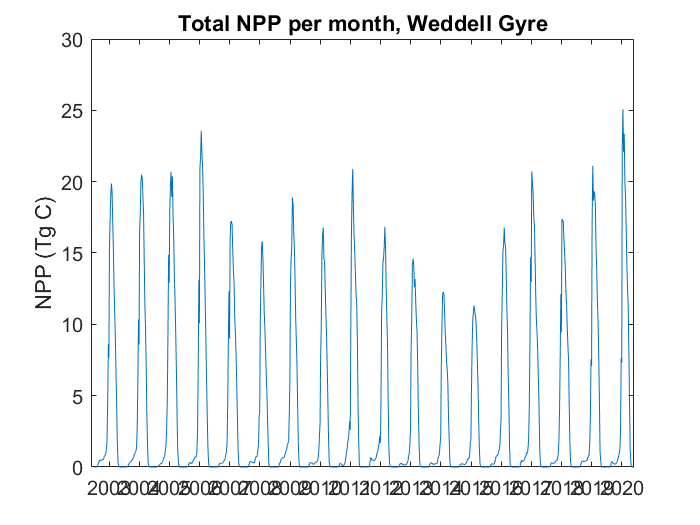

timedec_mid_npp=mean([timedec8day,timedec8day_end],2);
TotNPP_monthly=figure(1);
rix=1;
NPPmonth=plot(timedec_mid_npp,OceanProd_8day.cafe.(region_sublist{rix}).NPP_tot_TgC);
ylabel('NPP (Tg C)');
title('Total NPP per month, Weddell Gyre');
set(gca,'XLim',[2002.4 2020.4], 'FontSize', 12);
xticks(2003:1:2020);

## Seasonal Cycles

### NPP

Time (x) variables for NPP

load('ProcessedData_8day_May22.mat')
datenum_start=datenum(time_start_all);
datenum_end=datenum(time_end_all);
datenum_mid=mean([datenum_start,datenum_end],2);
datetime_mid=datetime(datenum_mid,'ConvertFrom','datenum');

datetime_aus=datetime_mid(1:46);

Plot NPP seasonal cycle

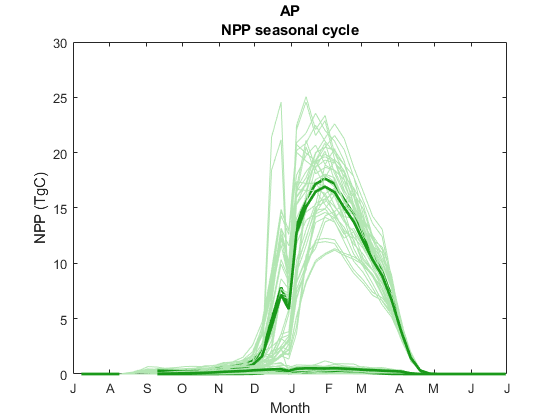

%close(MeanAusNPPtot)
MeanAusNPPtot=figure(2);
figure
for rix=1:length(region_sublist)
    NPPaus=plot(datetime_aus,OceanProd_8day.cafe.(region_sublist{rix}).NPP_tot_TgC_cols, 'Color',[0.7 0.9 0.7]);
    hold on
    NPPmaus=plot(datetime_aus,OceanProd_8day.cafe.(region_sublist{rix}).NPP_tot_TgC_mean,'Color',[0.1 0.6 0.1],'LineWidth',2);
    
    xlim([datetime_aus(1) datetime_aus(46)])
    datetick('x','m')
    ylabel('NPP (TgC)')
    xlabel('Month')
    str=({region_sublist{rix};'NPP seasonal cycle'});
    title(str)
end

### Sea Ice

Time (x) variables for Sea Ice 

load('SeaIcev4_8day_May22.mat')
for rix=1:length(region_sublist)
    SeaIce.(region_sublist{rix}).IFExtent_aus=SeaIce.g_area.(region_sublist{rix})-SeaIce.(region_sublist{rix}).SIExtent_aus;
    SeaIce.(region_sublist{rix}).IFExtent_aus_mean=mean(SeaIce.(region_sublist{rix}).IFExtent_aus,2);
    datenum_startice=datenum(time_start_8day_SICv4);
    datetime_ausice=datenum_startice(1:46);

Plot Ice-Free Extent seasonal cycle

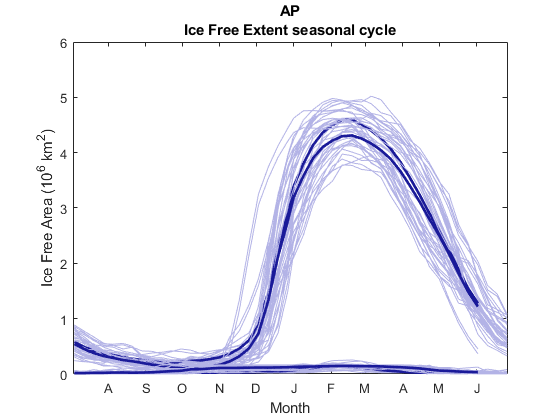

    %close(MeanAusSeaIce)
    MeanAusSeaIce=figure(3);
    IFEaus=plot(datetime_ausice,(SeaIce.(region_sublist{rix}).IFExtent_aus)/1e6, 'Color',[0.7 0.7 0.9]);
    hold on
    IFEmaus=plot(datetime_ausice,(SeaIce.(region_sublist{rix}).IFExtent_aus_mean)/1e6,'Color',[0.1 0.1 0.6],'LineWidth',2);
    datetick('x','m')
    
    xlim([datetime_ausice(1)-1.1 datetime_ausice(46)])
    ylabel('Ice Free Area (10^6 km^2)')
    xlabel('Month')
    str=({region_sublist{rix};'Ice Free Extent seasonal cycle'});
    title(str)
end

### Combine NPP and Sea Ice (Ice Free Extent) cycles

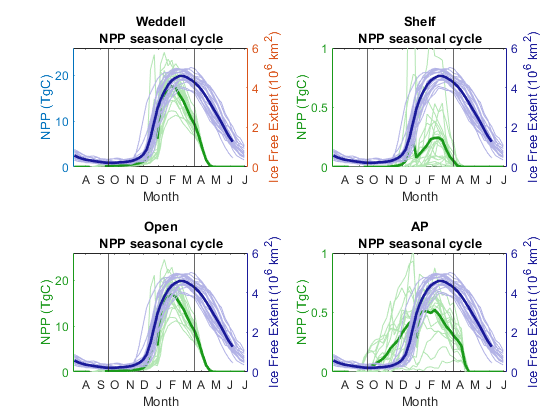

close(combinedAUS)
combinedAUS=figure(4);
for rix=1:length(region_sublist)
    nexttile
    left_color = [0.1 0.6 0.1];
    right_color = [0.1 .1 .6];
    set(combinedAUS,'defaultAxesColorOrder',[left_color; right_color]);
    yyaxis left
    NPPaus=plot(datetime_mid(1:46),OceanProd_8day.cafe.(region_sublist{rix}).NPP_tot_TgC_cols, ...
        'Color',[0.7 0.9 0.7],'LineStyle','-','Marker','none');
    ylabel('NPP (TgC)')
    if rix==1 || rix==3
        ylim([0 26])
    elseif rix==2||rix==4
        ylim([0 1])
    end
    hold on
    yyaxis right
    IFEaus=plot(datetime_mid(1:46),(SeaIce.Weddell.IFExtent_aus)/1e6,...
        'Color',[0.7 0.7 0.9],'LineStyle','-','Marker','none');
    ylabel('Ice Free Extent (10^6 km^2)')
    
    yyaxis left
    NPPmaus=plot(datetime_mid(1:46),OceanProd_8day.cafe.(region_sublist{rix}).NPP_tot_TgC_mean,...
        'Color',[0.1 0.6 0.1],'LineWidth',2,'LineStyle','-','Marker','none');
    yyaxis right
    IFEmaus=plot(datetime_mid(1:46),(SeaIce.Weddell.IFExtent_aus_mean)/1e6,...
        'Color',[0.1 0.1 0.6],'LineWidth',2,'LineStyle','-','Marker','none');
    datetick('x','m')
    xlim([datetime_mid(1)-3 datetime_mid(47)])
    xlabel('Month')
    str=({region_sublist{rix};'NPP seasonal cycle'});
    title(str)
    xline(datetime_mid(10))
    xline(datetime_mid(33))
end